clc; close all; clear;

% process_name = input('Enter the name of the process: ', 's');
process_name = 'Process 1';

process = Process(process_name);

[INFO from: Process 1]: Initiating process Process 1...



% rows = input('Enter the rows after discretizing the 2D space: ');
% cols = input('Enter the columns after discretizing the 2D space: ');

rows = 50;
cols = 50;

process = process.validate_env(rows, cols);

if ~process.valid_env
    return;
end


target = [27, 31];
initial = [9, 14];

process = process.validate_pos(initial, 'initial');
process = process.validate_pos(target, 'target');

if ~(process.valid_initial && process.valid_target)
    return;
end

obstacles = ones(40,2) * 25;

for i=1:40
    obstacles(i,2) = i + 5;
end

for i = 1 : size(obstacles, 1)
    process = process.validate_pos(obstacles(i, :), 'obstacle');
end

process = process.create_map();

process = process.q_learn();

[INFO from: Process 1]: Started learning...
[INFO from: Process 1]: Started learning... Done


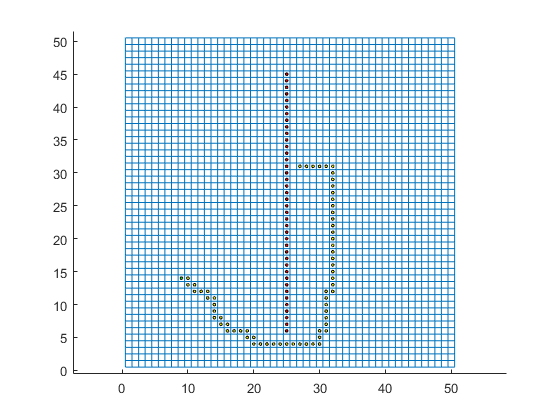


smoothing = 2;
process = process.create_path(smoothing);


plotMap(process.env, true);
plotCircle(process.initial(1), process.initial(2), 'g');
plotCircle(process.target(1), process.target(2), 'k');
for i = 1 : size(process.path, 1)
    plotCircle(process.path(i, 1), process.path(i, 2), 'y');
    hold on;
    pause(0.1);
end
hold off;

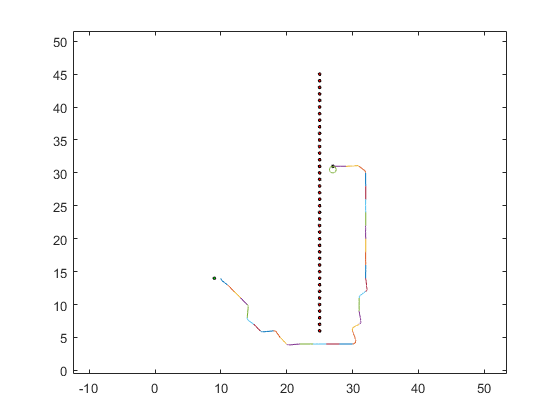


robot = TwoWheeledRobot(0.2, 1, pi, pi, pi);
angle = -pi / 2;

figure,
plotMap(process.env, false);
plotCircle(process.initial(1), process.initial(2), 'g');
plotCircle(process.target(1), process.target(2), 'k');
for i = 1 : size(process.smoothed_path, 1) - 1
    init = [process.smoothed_path(i, :), angle];
    dest = process.smoothed_path(i + 1, :);
    [modes, durations, ~] = robot.p2pReach(init, dest);
    allStates = robot.simulate(init, modes, durations, 0.01);
    plot(allStates(:, 1), allStates(:, 2));hold on;
    angle = allStates(end, end);
end
axis equal; 


process.display_info();

 Process Name: Process 1
 Rows in env: 50
 Columns in env: 50
 Initial position: 9, 14
 Target position: 27, 31
 Environment valid? 1
 Initial position valid? 1
 Target position valid? 1
